Robot1

L1(1) = Link('revolute','alpha',0,'a',0,'d',0.137,'offset',0,'modified');
L1(2) = Link('revolute','alpha',-pi/2,'a',0,'d',0,'offset',-pi/2,'modified');
L1(3) = Link('revolute','alpha',0,'a',0.105,'d',0,'offset',0,'modified');
L1(4) = Link('revolute','alpha',0,'a',0.105,'d',0,'offset',0,'modified');

R_tool = [0  0  1;
         -1  0  0;
          0 -1  0];
P_tool = [0.11 0 0]';
T_4_tool = rt2tr(R_tool,P_tool);
R1 = SerialLink(L1,'name','phantom1');
R1.tool = T_4_tool;
R1

 
R1 = 
 
phantom1 (4 axis, RRRR, modDH, slowRNE)                                        
                                                                               
+---+-----------+-----------+-----------+-----------+-----------+              
| j |     theta |         d |         a |     alpha |    offset |              
+---+-----------+-----------+-----------+-----------+-----------+              
|  1|         q1|      0.137|          0|          0|          0|              
|  2|         q2|          0|          0|     -1.571|     -1.571|              
|  3|         q3|          0|      0.105|          0|          0|              
|  4|         q4|          0|      0.105|          0|          0|              
+---+-----------+-----------+-----------+-----------+-----------+              
                                                                               
grav =    0  base = 1  0  0  0   tool =   0           0           1        0.11
          0         0  1  0  0

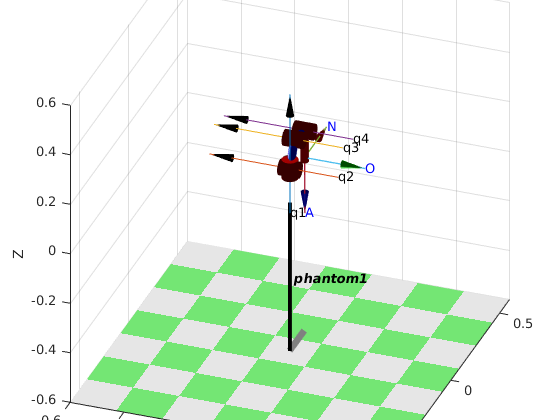




R1.plot([pi/2 0.4522 1.32 1.36],'noa','jvec','view',[20 30])

Robot2

L2(1) = Link('revolute','alpha',0,'a',0.5,'d',0.137,'offset',pi,'modified');
L2(2) = Link('revolute','alpha',-pi/2,'a',0,'d',0,'offset',-pi/2 ,'modified');
L2(3) = Link('revolute','alpha',0,'a',0.105,'d',0,'offset',0,'modified');
L2(4) = Link('revolute','alpha',0,'a',0.105,'d',0,'offset',0,'modified');

R_tool = [0  0  1;
         -1  0  0;
          0 -1  0];
P_tool = [0.11 0 0]';
T_4_tool = rt2tr(R_tool,P_tool);
R2 = SerialLink(L2,'name','phantom2');
R2.tool = T_4_tool;
R2

 
R2 = 
 
phantom2 (4 axis, RRRR, modDH, slowRNE)                                        
                                                                               
+---+-----------+-----------+-----------+-----------+-----------+              
| j |     theta |         d |         a |     alpha |    offset |              
+---+-----------+-----------+-----------+-----------+-----------+              
|  1|         q1|      0.137|        0.5|          0|      3.142|              
|  2|         q2|          0|          0|     -1.571|     -1.571|              
|  3|         q3|          0|      0.105|          0|          0|              
|  4|         q4|          0|      0.105|          0|          0|              
+---+-----------+-----------+-----------+-----------+-----------+              
                                                                               
grav =    0  base = 1  0  0  0   tool =   0           0           1        0.11
          0         0  1  0  0

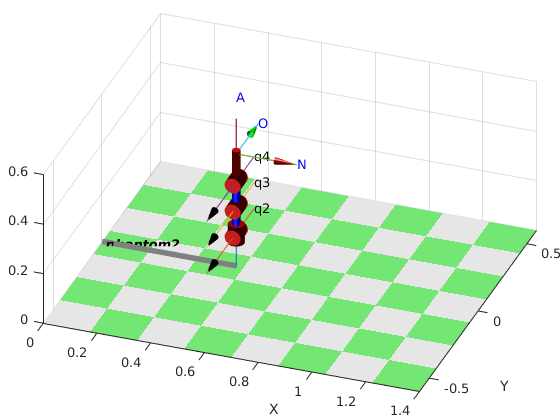




R2.plot([0 0 0 0],'workspace',[0 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

pic and place calculos

Primer punto

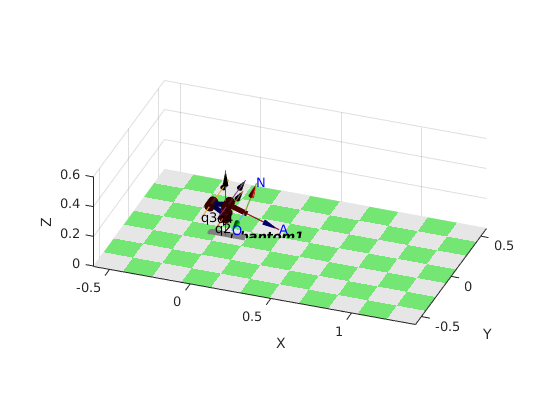

qi(1,:) =[0 -1 2.4 0.5 0 0];


R1.plot(qi(1,1:4),'workspace',[-0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

Segundo punto

entrada_x=0.075;
entrada_y=0.065;
x = 0.053+entrada_x;
y = 0.040+entrada_y;

Punto_aprox = [1  0  0  x;
               0 -1  0  y;
               0  0 -1  0.1;
               0  0  0  1];
Rot = rotz(atan2(y,x))*Punto_aprox(1:3,1:3);
MTH = rt2tr(Rot, [x y 0.1]')

MTH =     0.7731    0.6342         0    0.1280
    0.6342   -0.7731         0    0.1050
         0         0   -1.0000    0.1000
         0         0         0    1.0000


qi(2,:) = [R1.ikunc(MTH,qi(1,1:4)) 0 0] %llamamos la función

qi =          0   -1.0000    2.4000    0.5000         0         0
    0.6870    0.6231    1.0648    1.4537         0         0
    0.6870    0.8902    1.3249    0.9265         0         0
    0.6870    0.8902    1.3249    0.9265    0.0160    0.0160
    0.3366    0.5190    1.2258    1.3968    0.0160    0.0160
   -0.6871    1.2215   -0.0000    1.9074    0.0160    0.0160
   -0.6871    1.2758    0.5603    1.3055    0.0160    0.0160
   -0.6871    1.2758    0.5603    1.3055         0         0
   -0.6871    1.0068    0.0000    2.0640         0         0
         0   -1.0000    2.4000    0.5000         0         0


R1.fkine(qi(2,1:4))

ans =     0.7731    0.6342   -0.0000    0.1280
    0.6342   -0.7731   -0.0000    0.1050
   -0.0000   -0.0000   -1.0000    0.1000
         0         0         0    1.0000


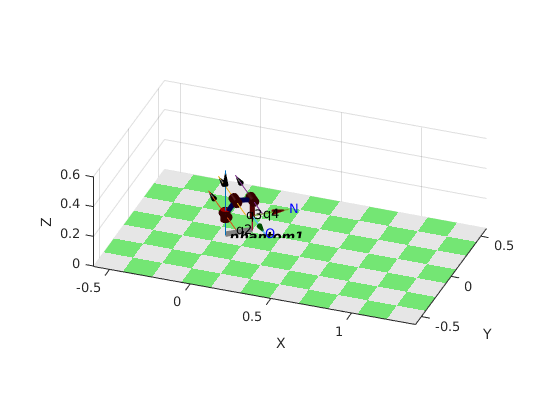

R1.plot(qi(2,1:4),'workspace',[-.05 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

Tercer punto 



Punto_aprox = [1  0  0  x;
               0 -1  0  y;
               0  0 -1  0.03;
               0  0  0  1];
MTH = rt2tr(Rot, [x y 0.03]')

MTH =     0.7731    0.6342         0    0.1280
    0.6342   -0.7731         0    0.1050
         0         0   -1.0000    0.0300
         0         0         0    1.0000


qi(3,:) = [R1.ikunc(MTH,qi(2,1:4)) 0 0] %llamamos la función

qi =          0   -1.0000    2.4000    0.5000         0         0
    0.6870    0.6231    1.0648    1.4537         0         0
    0.6870    0.8902    1.3249    0.9265         0         0
    0.6870    0.8902    1.3249    0.9265    0.0160    0.0160
    0.3366    0.5190    1.2258    1.3968    0.0160    0.0160
   -0.6871    1.2215   -0.0000    1.9074    0.0160    0.0160
   -0.6871    1.2758    0.5603    1.3055    0.0160    0.0160
   -0.6871    1.2758    0.5603    1.3055         0         0
   -0.6871    1.0068    0.0000    2.0640         0         0
         0   -1.0000    2.4000    0.5000         0         0


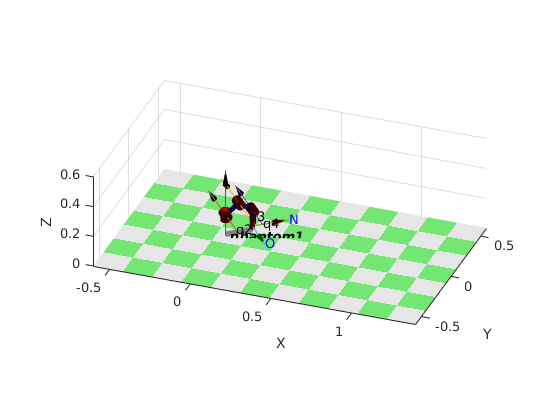

R1.plot(qi(3,1:4),'workspace',[-0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

qi(4,:) = [qi(3,1:4) 0.016 0.016];

Punto_aprox = [1  0  0  x;
               0 -1  0  y;
               0  0 -1  0.1;
               0  0  0  1];
qi(5,:) = [R1.ikunc(Punto_aprox,qi(4,1:4)) 0.016 0.016] %llamamos la función

qi =          0   -1.0000    2.4000    0.5000         0         0
    0.6870    0.6231    1.0648    1.4537         0         0
    0.6870    0.8902    1.3249    0.9265         0         0
    0.6870    0.8902    1.3249    0.9265    0.0160    0.0160
    0.3366    0.5190    1.2258    1.3968    0.0160    0.0160
   -0.6871    1.2215   -0.0000    1.9074    0.0160    0.0160
   -0.6871    1.2758    0.5603    1.3055    0.0160    0.0160
   -0.6871    1.2758    0.5603    1.3055         0         0
   -0.6871    1.0068    0.0000    2.0640         0         0
         0   -1.0000    2.4000    0.5000         0         0


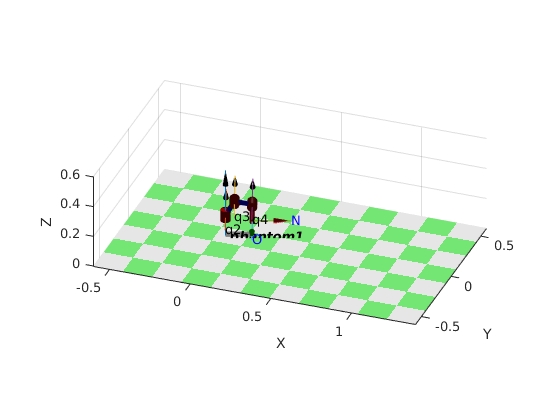

R1.plot(qi(5,1:4),'workspace',[-0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

Punto_aprox = [1  0  0  0.128;
               0 -1  0 -0.156;
               0  0 -1  0.10;
               0  0  0  1];
Rot = rotz(atan2(-0.128,0.156))*Punto_aprox(1:3,1:3);
MTH = rt2tr(Rot, [0.156 -0.128  0.10]')

MTH =     0.7731   -0.6343         0    0.1560
   -0.6343   -0.7731         0   -0.1280
         0         0   -1.0000    0.1000
         0         0         0    1.0000


qi(6,:) = [R1.ikunc(MTH,qi(5,1:4)) 0.016 0.016] %llamamos la función

qi =          0   -1.0000    2.4000    0.5000         0         0
    0.6870    0.6231    1.0648    1.4537         0         0
    0.6870    0.8902    1.3249    0.9265         0         0
    0.6870    0.8902    1.3249    0.9265    0.0160    0.0160
    0.3366    0.5190    1.2258    1.3968    0.0160    0.0160
   -0.6871    1.2215   -0.0000    1.9074    0.0160    0.0160
   -0.6871    1.2758    0.5603    1.3055    0.0160    0.0160
   -0.6871    1.2758    0.5603    1.3055         0         0
   -0.6871    1.0068    0.0000    2.0640         0         0
         0   -1.0000    2.4000    0.5000         0         0


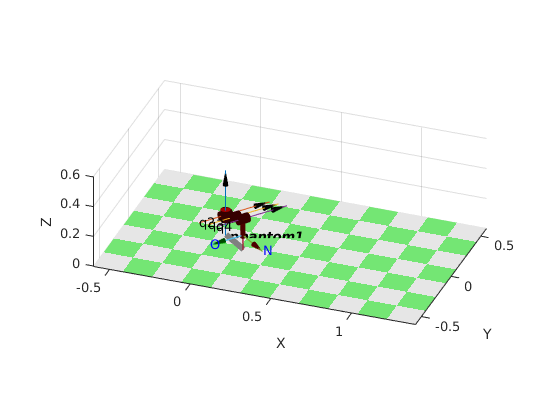

R1.plot(qi(6,1:4),'workspace',[-0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

Punto_aprox = [1  0  0  0.156;
               0 -1  0 -0.128;
               0  0 -1  0.03;
               0  0  0  1]

Punto_aprox =     1.0000         0         0    0.1560
         0   -1.0000         0   -0.1280
         0         0   -1.0000    0.0300
         0         0         0    1.0000


Rot = rotz(atan2(-0.128,0.156))*Punto_aprox(1:3,1:3);
MTH = rt2tr(Rot, [0.156 -0.128  0.03]')

MTH =     0.7731   -0.6343         0    0.1560
   -0.6343   -0.7731         0   -0.1280
         0         0   -1.0000    0.0300
         0         0         0    1.0000


qi(7,:) = [R1.ikunc(MTH,qi(6,1:4)) 0.016 0.016] %llamamos la función

qi =          0   -1.0000    2.4000    0.5000         0         0
    0.6870    0.6231    1.0648    1.4537         0         0
    0.6870    0.8902    1.3249    0.9265         0         0
    0.6870    0.8902    1.3249    0.9265    0.0160    0.0160
    0.3366    0.5190    1.2258    1.3968    0.0160    0.0160
   -0.6871    1.2215   -0.0000    1.9074    0.0160    0.0160
   -0.6871    1.2758    0.5603    1.3055    0.0160    0.0160
   -0.6871    1.2758    0.5603    1.3055         0         0
   -0.6871    1.0068    0.0000    2.0640         0         0
         0   -1.0000    2.4000    0.5000         0         0


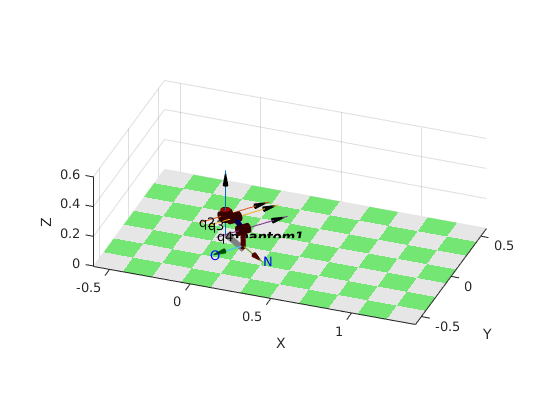

R1.plot(qi(7,1:4),'workspace',[-0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

qi(8,:) = [qi(7,1:4) 0 0];

Punto_aprox = [1  0  0  0.156;
               0 -1  0 -0.128;
               0  0 -1  0.1;
               0  0  0  1]

Punto_aprox =     1.0000         0         0    0.1560
         0   -1.0000         0   -0.1280
         0         0   -1.0000    0.1000
         0         0         0    1.0000


Rot = rotz(atan2(-0.128,0.156))*Punto_aprox(1:3,1:3);
MTH = rt2tr(Rot, [0.156 -0.128  0.10]')

MTH =     0.7731   -0.6343         0    0.1560
   -0.6343   -0.7731         0   -0.1280
         0         0   -1.0000    0.1000
         0         0         0    1.0000


qi(9,:) = [R1.ikunc(MTH,qi(7,1:4)) 0 0] %llamamos la función

qi =          0   -1.0000    2.4000    0.5000         0         0
    0.6870    0.6231    1.0648    1.4537         0         0
    0.6870    0.8902    1.3249    0.9265         0         0
    0.6870    0.8902    1.3249    0.9265    0.0160    0.0160
    0.3366    0.5190    1.2258    1.3968    0.0160    0.0160
   -0.6871    1.2215   -0.0000    1.9074    0.0160    0.0160
   -0.6871    1.2758    0.5603    1.3055    0.0160    0.0160
   -0.6871    1.2758    0.5603    1.3055         0         0
   -0.6871    1.2215    0.0000    1.9074         0         0
         0   -1.0000    2.4000    0.5000         0         0


R1.plot(qi(8,1:4),'workspace',[-0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

qi(10,:) = qi(1,:);

rosinit

The value of the ROS_MASTER_URI environment variable, http://localhost:11311, will be used to connect to the ROS master.
Initializing global node /matlab_global_node_44064 with NodeURI http://julian-XPS-8700:34349/


phantompos = rospublisher('/robot_1/phantom_position_controller/command');
message = rosmessage(phantompos)

message =   ROS Float64MultiArray message with properties:

    MessageType: 'std_msgs/Float64MultiArray'
         Layout: [1×1 MultiArrayLayout]
           Data: [0×1 double]

  Use showdetails to show the contents of the message


positionreal = rossubscriber('/robot_1/joint_states');
pause(1);

for i = 1:10
message.Data = qi(i,:);
send(phantompos,message);
states = receive(positionreal,2).Position;
states = round([states(3:6)' states(1:2)'],2)
while ( isequal( states, round(qi(i,:),2) ) == 0)
    states = receive(positionreal,1).Position;
    states = round([states(3:6)' states(1:2)'],2)
end
i = i+1;
end

states =          0   -1.0000    2.4000    0.5000         0         0


states =     0.0100   -0.9900    2.3900    0.5100         0         0


states =     0.0200   -0.9800    2.3800    0.5200         0         0


states =     0.0300   -0.9700    2.3700    0.5300         0         0


states =     0.0400   -0.9600    2.3600    0.5400         0         0


states =     0.0500   -0.9500    2.3500    0.5500         0         0


states =     0.0600   -0.9400    2.3400    0.5600         0         0


states =     0.0700   -0.9300    2.3300    0.5700         0         0


states =     0.0800   -0.9200    2.3200    0.5800         0         0


states =     0.6900    0.3700    1.0600    1.4500         0         0


states =     0.6900    0.6200    1.0600    1.4500         0         0


states =     0.6900    0.8900    1.3200    0.9300         0         0


states =     0.6900    0.8900    1.3200    0.9300    0.0200    0.0200


states =     0.3400    0.5200    1.2300    1.4000    0.0200    0.0200


states =    -0.5700    1.2200    0.3200    1.9100    0.0200    0.0200


states =    -0.6900    1.2200         0    1.9100    0.0200    0.0200


states =    -0.6900    1.2800    0.5600    1.3100    0.0200    0.0200


states =    -0.6900    1.2800    0.5600    1.3100         0         0


states =    -0.6900    1.2200         0    1.9100         0         0


states =          0    0.5000    0.7200    1.1800         0         0


states =          0   -0.2300    1.4500    0.5000         0         0


states =          0   -0.8700    2.0900    0.5000         0         0


states =          0   -1.0000    2.4000    0.5000         0         0



rosshutdown

Shutting down global node /matlab_global_node_44064 with NodeURI http://julian-XPS-8700:34349/
